clear;
format short
syms V R x wt
% R=10, V=440
iD1 = piecewise(0 <= wt & wt <= pi, sqrt(2)*V/R * sin(wt), ...
                pi < wt & wt <= 2*pi, 0)

$$iD1 = \left\{ \begin{array}{cl} \frac{\sqrt{2}\,V\,\sin\left(\mathrm{wt}\right)}{R} & \text{ if }\mathrm{wt}\in \left[0,\pi \right]\\ 0 & \text{ if }\mathrm{wt}\in \left(\pi ,2\,\pi \right] \end{array}\right.$$

iD1_avg= 1/2/pi * int(iD1, 'wt', [0 2*pi], hold=0); vpa(iD1_avg)

$$ans = \frac{0.45015815807855306260745103910153\,V}{R}$$

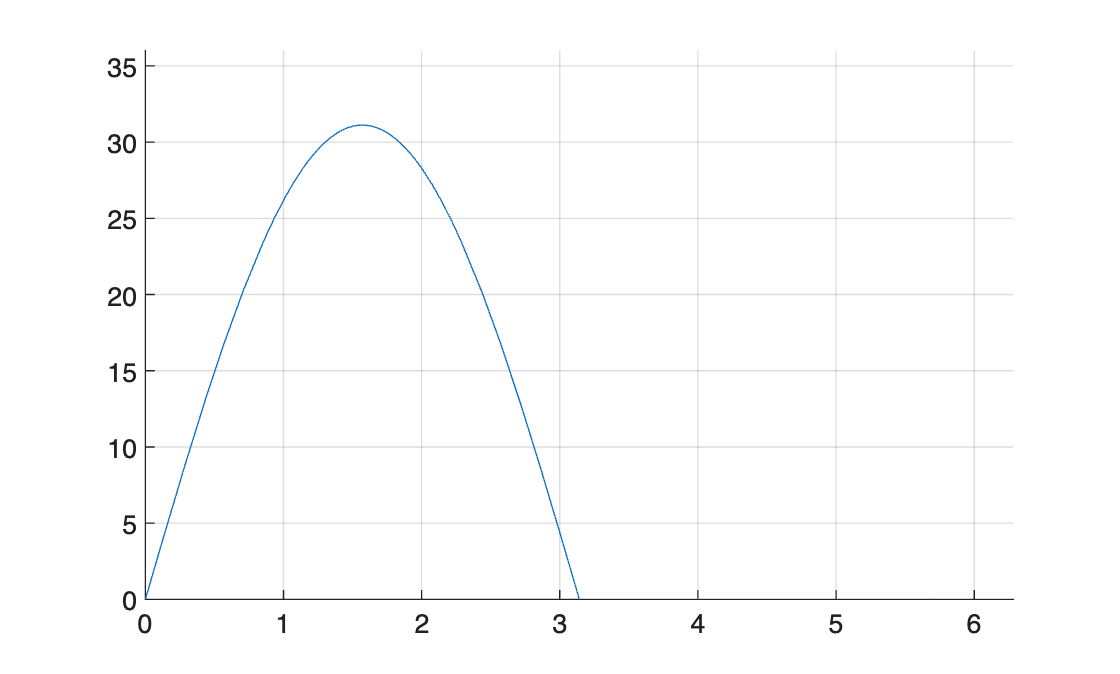

figure; 
hold on; grid on;
axis([0 2*pi 0 36]); 
fplot(subs(iD1, [V R], [220 10]));

v_avg=1/pi*int(sqrt(2)*V*sin(wt), 'wt', [0 pi]); vpa(v_avg)

$$ans = 0.90031631615710612521490207820306\,V$$